# Analyses Courbes moteurs

Courbes moteurs

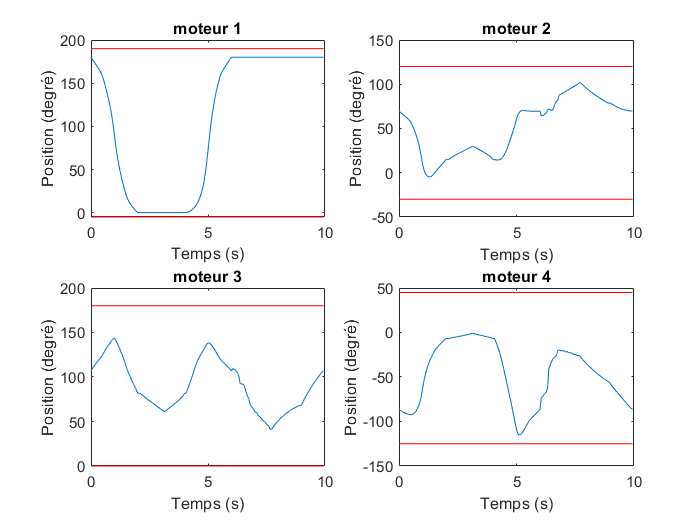

figure('Name','Angles en fonction de tau');

subplot(2,2,1);
plot(arc(4,:),configurationCycle(1,:), ...
    arc(4,:),rad2deg(limiteAngle.Bounds(1,1))*ones(length(configurationCycle)),"-r", ...
    arc(4,:),rad2deg(limiteAngle.Bounds(1,2))*ones(length(configurationCycle)),"-r");
xlabel("Temps (s)");
ylabel("Position (degré)");
title("moteur 1");

subplot(2,2,2);
plot(arc(4,:),configurationCycle(2,:), ...
    arc(4,:),rad2deg(limiteAngle.Bounds(2,1))*ones(length(configurationCycle)),"-r", ...
    arc(4,:),rad2deg(limiteAngle.Bounds(2,2))*ones(length(configurationCycle)),"-r");
xlabel("Temps (s)");
ylabel("Position (degré)");
title("moteur 2");

subplot(2,2,3);
plot(arc(4,:),configurationCycle(3,:), ...
    arc(4,:),rad2deg(limiteAngle.Bounds(3,1))*ones(length(configurationCycle)),"-r", ...
    arc(4,:),rad2deg(limiteAngle.Bounds(3,2))*ones(length(configurationCycle)),"-r");
xlabel("Temps (s)");
ylabel("Position (degré)");
title("moteur 3");

subplot(2,2,4);
plot(arc(4,:),configurationCycle(4,:), ...
    arc(4,:),rad2deg(limiteAngle.Bounds(4,1))*ones(length(configurationCycle)),"-r", ...
    arc(4,:),rad2deg(limiteAngle.Bounds(4,2))*ones(length(configurationCycle)),"-r");
xlabel("Temps (s)");
ylabel("Position (degré)");    
title("moteur 4");

Vitesse moteurs

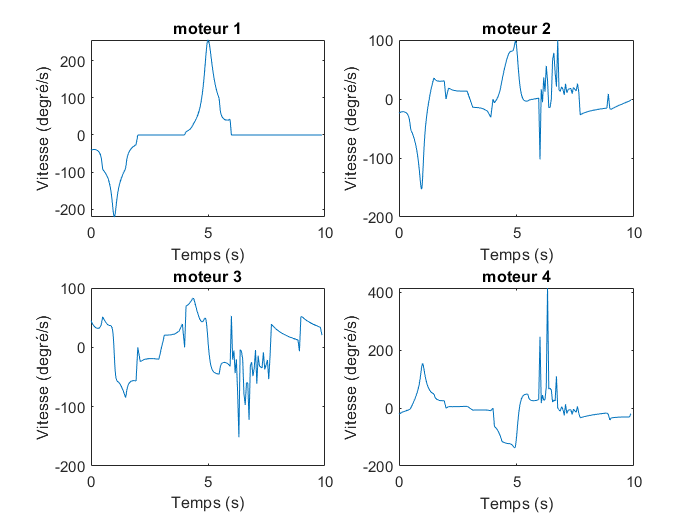

vitesseMot=zeros(4,length(configurationCycle)-1);
vitesseMot(1,:)=diff(configurationCycle(1,:))./diff(arc(4,:));
vitesseMot(2,:)=diff(configurationCycle(2,:))./diff(arc(4,:));
vitesseMot(3,:)=diff(configurationCycle(3,:))./diff(arc(4,:));
vitesseMot(4,:)=diff(configurationCycle(4,:))./diff(arc(4,:));

figure;

subplot(2,2,1);
plot(arc(4,1:end-1),vitesseMot(1,:));
xlabel("Temps (s)");
ylabel("Vitesse (degré/s)");    
title("moteur 1");

subplot(2,2,2);
plot(arc(4,1:end-1),vitesseMot(2,:));
xlabel("Temps (s)");
ylabel("Vitesse (degré/s)");    
title("moteur 2");

subplot(2,2,3);
plot(arc(4,1:end-1),vitesseMot(3,:));
xlabel("Temps (s)");
ylabel("Vitesse (degré/s)");    
title("moteur 3");

subplot(2,2,4);
plot(arc(4,1:end-1),vitesseMot(4,:));
xlabel("Temps (s)");
ylabel("Vitesse (degré/s)");    
title("moteur 4");

Accélération moteurs

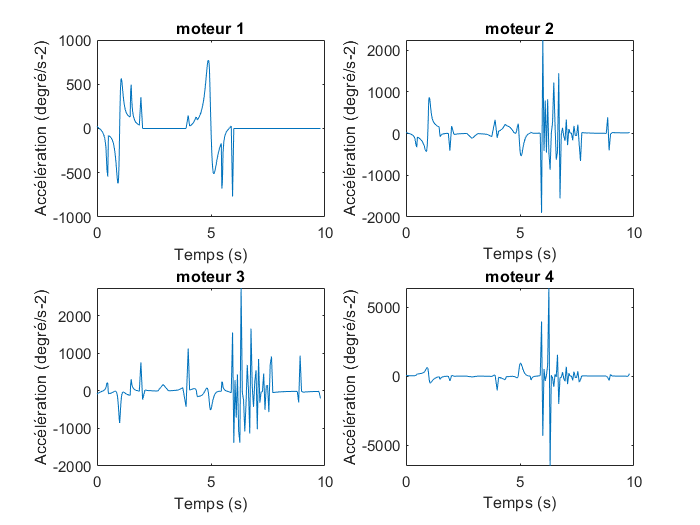

accelMot=zeros(4,length(vitesseMot)-1);
accelMot(1,:)=diff(vitesseMot(1,:))./diff(arc(4,1:end-1));
accelMot(2,:)=diff(vitesseMot(2,:))./diff(arc(4,1:end-1));
accelMot(3,:)=diff(vitesseMot(3,:))./diff(arc(4,1:end-1));
accelMot(4,:)=diff(vitesseMot(4,:))./diff(arc(4,1:end-1));

figure;

subplot(2,2,1);
plot(arc(4,1:end-2),accelMot(1,:));
xlabel("Temps (s)");
ylabel("Accélération (degré/s-2)");    
title("moteur 1");

subplot(2,2,2);
plot(arc(4,1:end-2),accelMot(2,:));
xlabel("Temps (s)");
ylabel("Accélération (degré/s-2)");    
title("moteur 2");

subplot(2,2,3);
plot(arc(4,1:end-2),accelMot(3,:));
xlabel("Temps (s)");
ylabel("Accélération (degré/s-2)");    
title("moteur 3");

subplot(2,2,4);
plot(arc(4,1:end-2),accelMot(4,:));
xlabel("Temps (s)");
ylabel("Accélération (degré/s-2)");    
title("moteur 4");